## Global climate: how can differential equations make a difference?

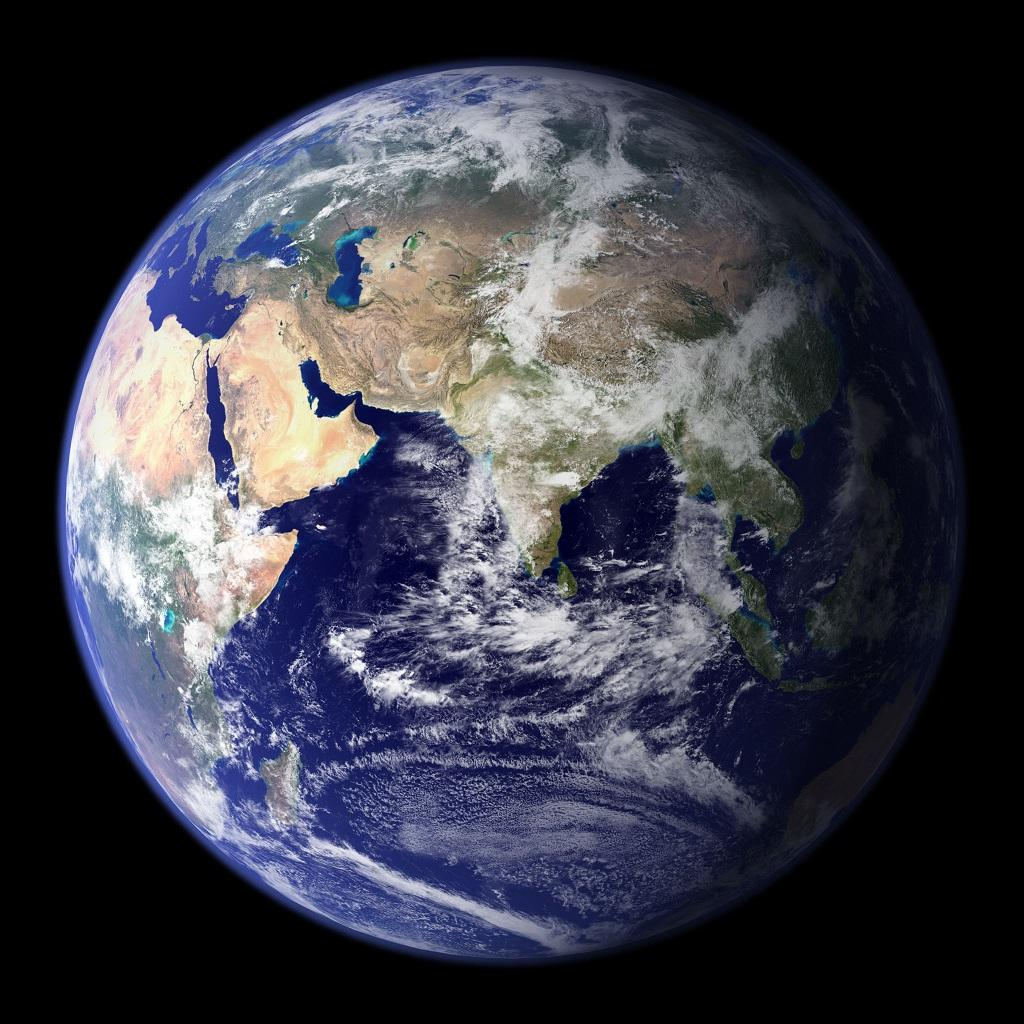

*Image credit: Visible Earth.* *Image by Reto Stöckli, Render by Robert Simmon. Based on data from the *[*MODIS Science Team*](http://modarch.gsfc.nasa.gov/)*. Available online: *[*https://visibleearth.nasa.gov/images/2181/the-blue-marble*](https://visibleearth.nasa.gov/images/2181/the-blue-marble)*.*

Recent data indicates that Earth's surface temperature has been rising. This troubling data has led to resolutions across the globe to reduce carbon emissions. What role do differential equations play in the science that has led to these resolutions?

Climate models assembled from differential equations are the key to understanding climate change. They allow us to model why changes have happened and predict what changes may occur in the future. In this module, you will learn how to analyze first order differential equations and apply them to study a first order energy balance climate model.

# Slope Fields

## Getting started with the Slope Field app

In this lesson, you will use the Slope Field app to interactively analyze ODEs. Get started with the app by completing the following activity.

    **Activity. **

        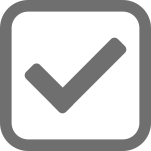  Visit the [GitHub repository](https://github.com/MathWorks-Teaching-Resources/Phase-Plane-and-Slope-Field) and watch the Slope Field app tutorial. You can find the tutorial videos in the [GitHub readme](https://github.com/MathWorks-Teaching-Resources/Phase-Plane-and-Slope-Field#Getting-Started).

          Download the repository code which contains the app by clicking the **Code **button and selecting **Download ZIP**. Unzip the downloaded repository and open the folder containing the files inside MATLAB. 

         Open the Slope Field app by right-clicking the app and selecting **run**. Generate a solution with initial values $x(0)=1$ using the default equation. The solution curve should appear as shown in the figure below.

 The app requires a recent MATLAB release (the required release is stated in the GitHub repository). If you're running an older version of MATLAB, download the [latest version](https://www.mathworks.com/downloads/) of MATLAB or open the app in [MATLAB Online](https://matlab.mathworks.com/) instead.

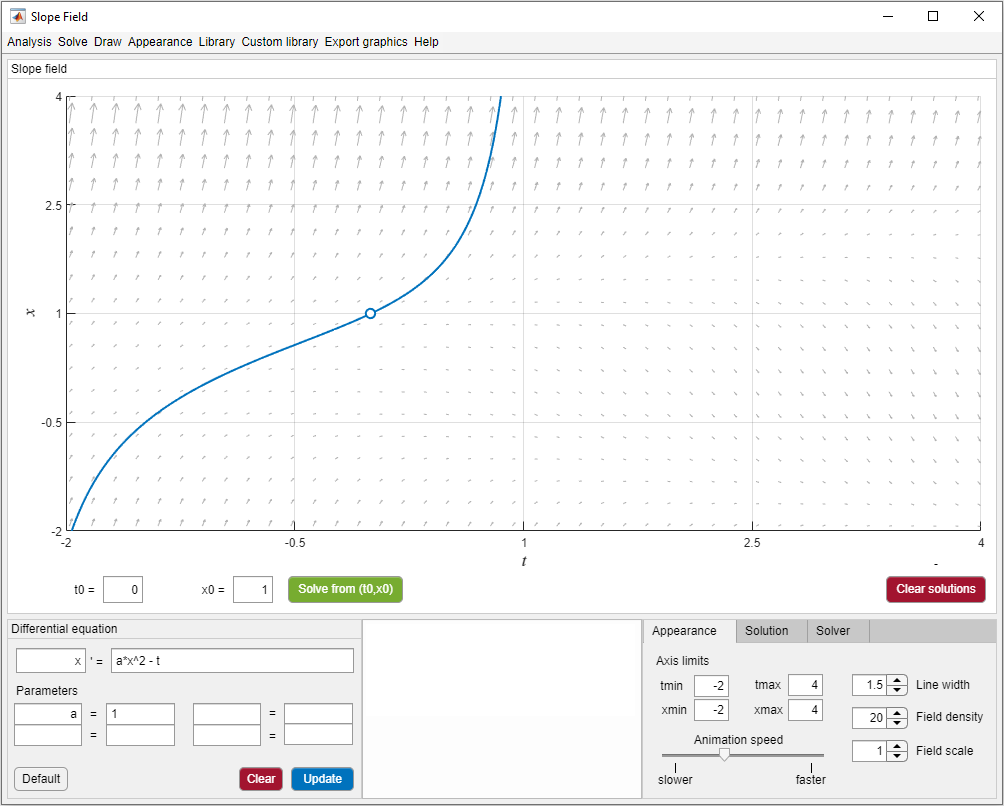

*Solution to the default ODE *$x'(t) = ax^2 - t$* with *$x(0) = 1$*.*

## Autonomous ODEs

**Definition.** An *autonomous* ODE has no explicit dependence on the independent variable (here denoted $t$). An autonomous ODE can be written in the form

$F(y,y',y'',...) = 0$.

The *order* of an ODE is the highest derivative present.

Note that $y'$ refers to the derivative and is used interchangeably with $\frac{dy}{dt}$. Higher order derivatives are indicated with additional single quotes or numbers in parentheses. For example, $y^{(5)}$ represents the fifth derivative.

 **Example. **Which of the ODEs are autonomous? What is the order of the ODE?

-  
$$y'' + y' -5 = 0$$


-  
$$y^{(4)} + t^2 =  0$$


**Solution.** 

-  $y'' + y' -5 = 0$ is a second order autonomous ODE because it only depends on the derivatives of $y$.

-  $y^{(4)} + t^2 =  0$ is a fourth order non-autonomous ODE due to the explicit $t$ dependence of the $t^2$ term. 

** Exercise. **Which of the following ODEs are autonomous? The independent variable in each case is $t$.

    (1) $\frac{dx}{dt} = \sin(x)$        (2) $\phi''(t)= t$        (3) $y'' - y' + 2 = 0$        (4) $y^{(5)} = ty$        (5) $x' = ax^2 - t$

Write your answer as a comma separated list (e.g. 1,4) in the space provided.

autonomousList = [1, 3]; 
checkWhichAutonomous(autonomousList) % Checks your answer

**  Reflect.** 

- What are the orders of the ODEs?

- Do you recognize any of these ODEs as describing a physical system?

** Application exercise. **In a simple energy balance model (EBM), the temperature on the surface of the Earth is modeled by:

   change of temperature $\propto$ (incoming radiation - outgoing radiation)

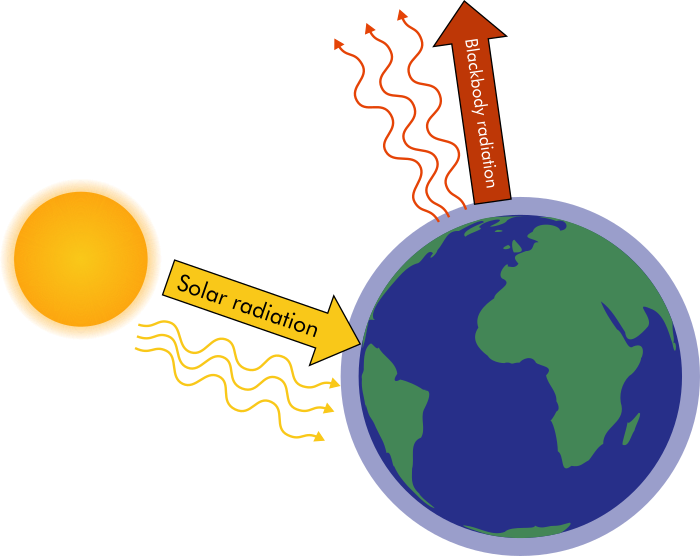

*Illustration of the Earth's energy balance: solar radiation from the sun warms the Earth. Heat is radiated from the Earth in the infrared spectrum (known as blackbody radiation).*

A simplified EBM represents this proportionality through the ODE:


$$\frac{dT}{dt} = a - bT^4$$


where $T$ is the global annual average surface temperature, $t$ is the time in years, and $a$ and $b$ are positive constants.

- Is the EBM ODE autonomous?

- What is the order of the EBM ODE?

- Which term corresponds to incoming radiation? Which to outgoing?

showAnswersEBM(true) % Click to show the answers

 Note that climate modeling is notoriously challenging, and the simplified energy balance model is woefully insufficient for this problem. However, even this simple first order ODE model can help you build intuition about the climate and provide a basis for understanding more complicated models.

## Slope fields

First order differential equations can be visually characterized by a *slope field*. The slope field plots the derivatives at many points in the $x$-$t$ plane (i.e., the plane that plots the dependent variable against the independent). The derivative is represented as the slope of a short line or vector. The derivative of a first order ODE may always be written as a function of the independent variable and one dependent variable. This implies that the slope field can be created for both autonomous and non-autonomous ODEs. 

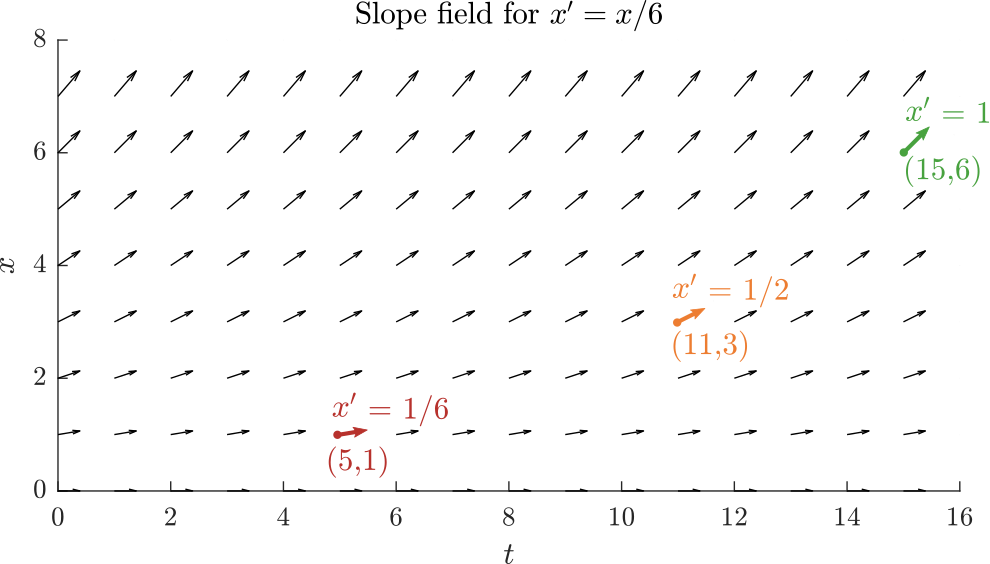

*Example slope field for *$x' = x/6$*. At each point, the derivative is computed by plugging *$x$ and $t$* into the ODE. The derivative is displayed as the slope of a vector. Note that for this autonomous ODE the slope field does not vary with time, *$t$.

### Creating slope fields

While it is informative to draw slope fields by hand, in this lesson, you will use software. This allows you to create detailed slope fields quickly and accurately.

 **Example. **Generate a slope field for the first order differential equation.


$$x'(t) = x-t + 3$$


**Solution. **To generate the slope field, start by creating a mesh of points in the plane using [`meshgrid`](https://www.mathworks.com/help/matlab/ref/meshgrid.html).

 
x = 0:0.5:5; % x locations
t = 0:0.5:10; % t locations
[Tmesh,Xmesh] = meshgrid(t,x); % create matrices T and X that are arrays of points through the plane
Tmesh
Xmesh

Then, evaluate the derivative function: $f(t,x) = x - t + 3$ and use the [`quiver`](https://www.mathworks.com/help/matlab/ref/quiver.html) function to plot the slope field using arrows.

 
f = Xmesh-Tmesh+3; % Computes the values of f(t,x)
quiver(Tmesh,Xmesh,ones(size(Tmesh)),f) % Plots the field arrows
axis([min(t) max(t) min(x) max(x)]) % Automatically scales the axes
xlabel("t")
ylabel("x")

    **Activity. **In this activity, you will use the Slope Field app to generate slope fields rather than writing code in MATLAB. Start by opening the Slope Field app and then follow the instructions below.

            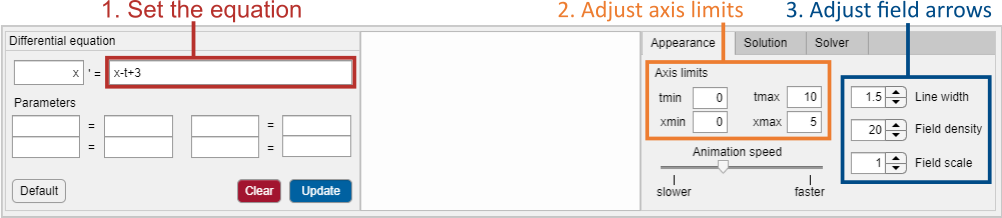

**Task 1.** The app automatically displays the slope field when you update the equation. Try setting the ODE to $x' = x - t + 3$ and then click **Update**. Does the slope field match the one shown in the preceding example?

**Task 2. **The default axis limits in the slope field app are a bit different than those used to generate the graph above. Try adjusting the axis limits to $t: [0,10]$, $x: \ [0,5]$.

**Task 3. **That looks similar, but there are a lot of arrows. Try adjusting the field density and scale until you can see the directions indicated by the slope field arrows clearly. If the size difference of the arrows makes it difficult to see the directions, select **Field orientation only** from the **Appearance** drop-down menu.

**Task 4. **Generate fields for the equations shown below. 

                **a.** $x' = x-2$        **b.** $y' = \sin(y)\sin(t)$        **c.** $r' = r(r-2)$

 You need to use an asterisk (`*`) when writing multiplication in the ODE definition. So, for example, write the RHS of **b.** as 

**  Reflect.** 

- Are there systematic differences between the slope fields of autonomous and non-autonomous ODEs?

- In **c.**, how do the zeros of the right-hand side function ($r = 0$ and $r = 2$) show up in the slope field?

### Drawing ODE solutions on the slope field

Solution curve slopes always match the slope field. Because of this, you can use slope fields to draw solutions of an ODE. 

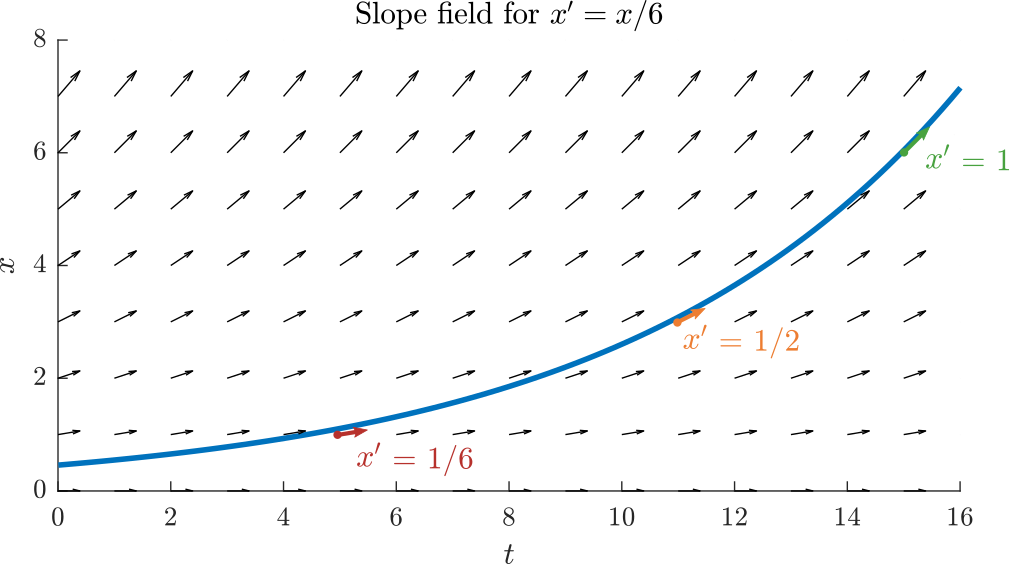

*A solution curve *$x(t) = \frac{1}{2} e^{t/6}$ *plotted on the slope field of *$x' = x/6$*. Notice that the slope of the solution curve matches the slope field.*

 **Example. **Consider the ODE

$\frac{dy}{dt} = -y^2 t$,  $y(0) = 2$

**a. **Solve the initial value problem using separation of variables.

**b.** Plot the solution on the slope field.

**Solution. **

**a.** Separate the variables:


$$-\frac{1}{y^2} \ dy = t \ dt$$


and integrate:


$$\frac{1}{y} = \frac{t^2}{2} + C$$


Applying the initial condition yields the final solution:


$$\frac{1}{2} = C$$
   
$$\rightarrow$$
    
$$\frac{1}{y} = \frac{t^2}{2} + \frac{1}{2}$$
    
$$\rightarrow$$
    
$$y = \frac{2}{t^2 + 1}$$


**b. **Click **show plot **below to plot the analytic solution on the slope field. Notice how the solution follows the slope field.

 
plotLorentzian % Helper function that plots the solution and field

**  Reflect.** 

- In your mind, try drawing the solution starting at $y(0) = 1$. How does it compare to the solution through $y(0) = 2$?

   **Activity. **In this activity, you will use the slope field app to draw solutions of an ODE. 

**Task 1. **Open the app and update the slope field to use the ODE from the previous example:


$$\frac{dy}{dt} = -y^2 t$$


**Task 2. **It's difficult to see some of the field arrows in the equation. Adjust the appearance of the arrows by selecting **Appearance** > **Field orientation only**. Also, set the axis limits to $t: [0, 4]$ and $y: [0,2]$.

**Task 3.** Visualize the solution with$y(0) = 2$. To accurately set the initial condition, use the edit fields. 

            

Does your solution match the one shown in the previous example?

**Task 4. **Draw a solution starting at $y(0) = 1$ that follows the slope field. To do so, select **Draw and compare solution** from the **Draw** drop-down menu. Click once to start drawing, draw your solution curve, and then click again to stop drawing. 

Drawing the solution with a mouse can be a challenge, so don't worry if your solution doesn't match perfectly. Your drawing should look similar to the one shown below.

        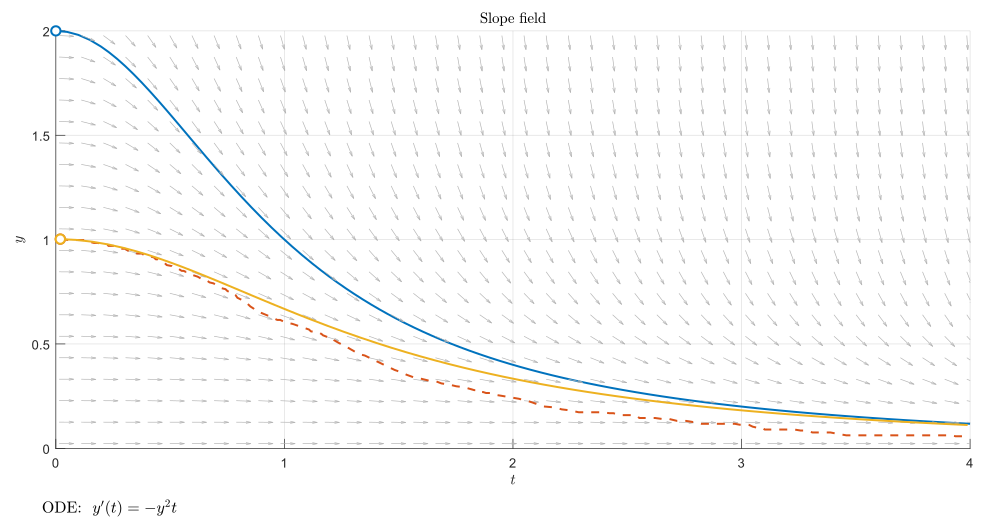

**Task 5. **Try drawing four additional solutions to the ODE starting at different locations in the slope field. The app estimates your accuracy each time you draw a curve and displays the result in the dialogue window. Are you able to achieve accuracy > 90%? 

** Application. **The EBM climate model estimates the change of temperature on the surface of the Earth through

   change of temperature $\propto$ (absorbed incoming radiation - outgoing radiation)

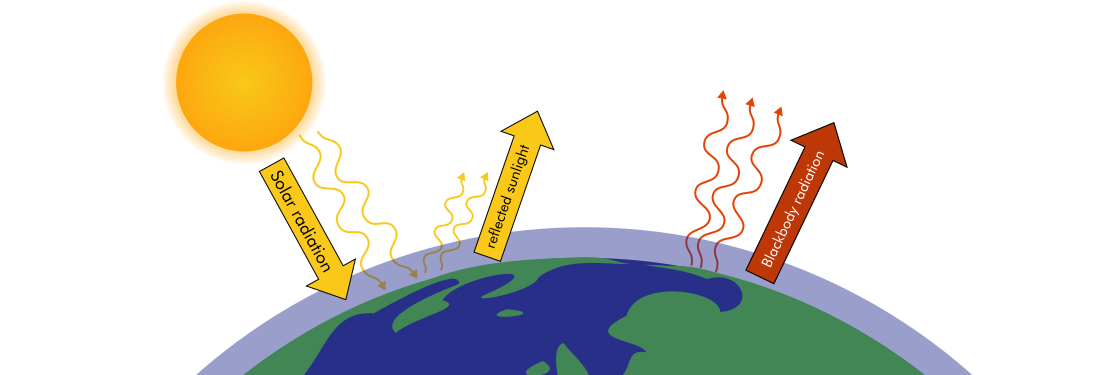

*The Earth doesn't absorb all of the sunlight that reaches it. Some of it is reflected.*

The absorbed incoming radiation will vary according to ground type: lighter surfaces, like snow, reflect more light. The proportion of light reflected by the surface of a planet is known as a*lbedo*. For ice-albedo feedback, albedo varies as a function of surface temperature. As temperatures rise, ice and snow melt, decreasing the albedo. The equation below defines a rough estimate for this phenomenon.


$$\alpha(T) = 0.5 +  0.2 \tanh(26.5 - 0.1T)$$


This albedo function is plotted below.

 
T = 200:350; % [K] Temperature array
albedo = 0.5 + 0.2*tanh(26.5 - 0.1*T); % Computes the albedo function
plot(T,albedo) % Plots the albedo function
xlabel("T [K]")
ylabel("albedo")

Notice that at freezing temperatures ( < 273.15 K ), the albedo constant is higher. That happens because there is more snow and ice, leading to increased reflection of solar radiation.

The absorbed radiation is proportional to $1-\alpha(t)$. So, using this albedo function, the EBM ODE becomes


$$\frac{dT}{dt} = a(0.5 -  0.2 \tanh(26.5 - 0.1T)) - b T^4$$


where $t$ is the time in years and the parameters are $a = 55$ and $b = 5.7 \cdot 10^{-9}$.

**Task 1. **Update the equation and parameters in the Slope Field app to the EBM equations. Also, set the axis range to $t: [0, 20]$ years and $T:[200,320]$ Kelvin. Ensure that the drop-down option **Appearance > Field orientation only **is turned on.

 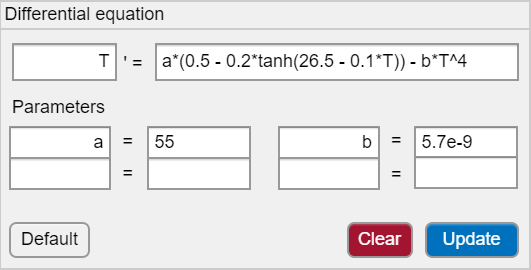

**Task 2. **If the mean global temperature $T$ starts at 320 K (116$^\circ$F), do you expect the Earth to warm or cool? To find out what this simple EBM model predicts, draw a solution to the ODE starting at $T(0) = 320$ using **Draw >** **Draw and compare solution.**

**Task 3. **If the temperature begins well below freezing (in Kelvin, 273.15 is the freezing temperature of water) at T = 200 K, do you expect the Earth to warm or cool? Try drawing a solution through the slope field starting at $T(0) = 200$.

**Task 4. **Repeat the process, but this time start at freezing: $T = 273.15$ K.

**  Reflect.** 

- Based on the solutions you observed, how would you characterize the long-term behavior of the Earth's surface temperature as predicted by this model?

- Eventually, all solutions of this model will converge on two $T$ values. What are the two values of the long-term mean global temperatures predicted by this model?

**Visualizations**

function plotLorentzian
    % helper function that generates the slope field
    plotDirectionFieldOrientationOnly(@(t,y)-y.^2.*t,[0 4],[0 2],15); 
    
    % Plot the specific solution
    t = linspace(0,4.1,500);
    hold on 
    plot(t,2./(t.^2+1)) 
    hold off
    axis tight
    xlabel("$t$","interpreter","latex")
    ylabel("$y$","interpreter","latex")
    box off
end

function plotDirectionFieldOrientationOnly(dydt,tlim,ylim,N)
    % Creates a slope field with rescaled arrows
    [T,Y,u,v] = setupDirectionField(dydt,tlim,ylim,N);
    orientationQuiver(T,Y,u,v,1.1,gca);
end

function [T,Y,u,v] = setupDirectionField(dydt,tlim,ylim,N)
    % Sets up the slope field
    t = linspace(tlim(1),tlim(2),N);
    y = linspace(ylim(1),ylim(2),N);
    [T,Y] = meshgrid(t,y);
    derivativeField = dydt(T,Y);
    u = ones(size(T));
    v = derivativeField.*u;
    axis([tlim,ylim])
    xlabel("$t$","interpreter","latex")
    ylabel("$y$","interpreter","latex")
end

function quiverHandle = orientationQuiver(x,y,vx,vy,scale,axisHandle)
    % Generates a vector field with normalized lengths
    % Set the axis limits and figure size before calling this function
    % as it determines the scaling based on the current axes
    dataAspectRatio = axisHandle.DataAspectRatio;
    plotBoxAspectRatio = axisHandle.PlotBoxAspectRatio;
    arx = dataAspectRatio(1)./plotBoxAspectRatio(1);
    ary = dataAspectRatio(2)./plotBoxAspectRatio(2);
    mags = sqrt(vx.^2 + vy.^2);
    vx = vx./mags;
    vy = vy./mags;
    nv = sqrt( (vx.*ary).^2 + (vy.*arx).^2 );
    quiverHandle = quiver(axisHandle,x,y,vx./nv,vy./nv,scale*0.5);

end


**Checks**

function checkWhichAutonomous(autonomousList)
    isEqualCheck([1 3],autonomousList)
end

function isEqualCheck(userSubmission,correctAnswer)
    % This function checks if two results are equal and displays feedback
    if( isequal(userSubmission, correctAnswer) )
        disp("Correct!")
    else
        warning("Your answer does not match the expected result.")
    end
end

**Answers**

function showAnswersEBM(showAns)
    if(showAns)
        disp("Autonomous (no explicit dependance on t)")
        disp("First order (T^4 is not a derivative)")
        disp("Incomming: a,  Outgoing: -b*T^4")
    end
end

**Suppressed suggestions**

 %#ok<*NBRAK>  